Εργασία matlab

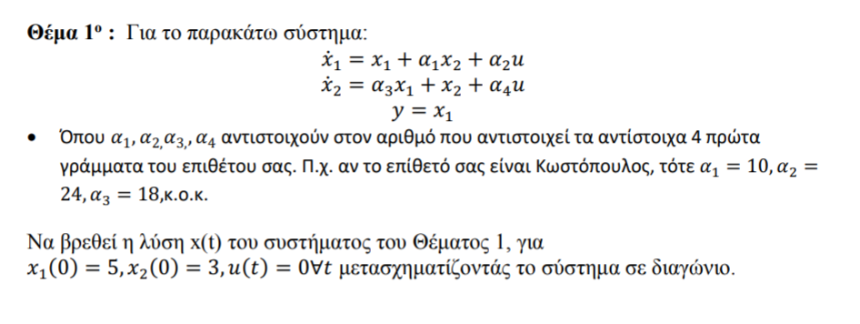

Η επίλυση έγινε σε matlab live.

clear all ;
clc;
a1 = 10;
a2 = 1;
a3 = 12;
a4 = 1;

a = [ a1 a2 a3 a4];

A = [ 1 a(1) ; a(3) 1];
B = [a(2) ; a(4)];
C = [ 1  0];
D = 0;

Αρχικά έχουμε τις μεταβλητές κα τις Α B C D. Συνεχίζουμε έπειτα με την εύρεση ΚΜΦ

S = [ B A*B];
S_t = inv(S);
 
q = S_t(2,:);
P = [q ; q*A];

 
T= inv(P);
 
A_n = T^(-1) * A * T

A_n =     0.0000    1.0000
  119.0000    2.0000


B_n = T^(-1) * B

B_n =      0
     1


C_n = C * T

C_n =     9.0000    1.0000


D_n = D

D_n = 0

Έπειτα υπολογίζουμε τις ιδοτιμές και φτιάχνουμε τον πίνακα:

lamda = eig(A_n)

lamda =    -9.9545
   11.9545


lamda = round(lamda,4)

lamda =    -9.9545
   11.9545


T_new = [ 1 1 ; lamda(1) lamda(2)]

T_new =     1.0000    1.0000
   -9.9545   11.9545


Τώρα βρίσκουμε τον μοναδιαίο:

A_d = T_new^(-1) * A_n * T_new 

A_d =    -9.9545    0.0000
   -0.0000   11.9545


Εδώ έχω απορία καθώς δεν αναφέρεται αν τα υπόλοιπα βρίσκονται έτσι:

B_d = T_new^(-1) * B_n 

B_d =    -0.0456
    0.0456


δεν θα έπρεπε να βγαίνει 1 1 ;


C_d = C_n * T_new 

C_d =    -0.9545   20.9545


επίσης βγαίνει περίεργο.. κάνοντας άλλη επίλυση αυτόματη μου βγάζει άλλες τιμές


D_d = D_n 

D_d = 0

Έπειτα προχωράμε με την λύση του νέου συστήματος:

syms  t s X x(t) Dx(t) y x1 x2 X1 X2 x   x1(t) x2(t)
X = [ X1 ; X2];
x = [ x1  ; x2 ] ;

Εδώ θα πρέπει να πειράξουμε και τις αρχικές τιμές;

z0 = (T^-1)*[5;3];

και επίσης θα πρέπει να γίνει δύο φορές, και με το νέο T δηλαδη

z00 = (T_new^-1)*z0

z00 =    -1.1847
    0.1847


έτσι παίρνουμε τις νέες τιμές μας και λύνουμε:

%%1st eq edv splitara gt alliws de vrhka tropo
eqn1=sym('D(x1)(t) - (-6.1414)* x1(t)= -0.0456*e^(5*t)'); % douleyei mono gia 17 a,b kai katw

lteqn1=laplace(eqn1,t,s);
neweqn1=subs(lteqn1,{'laplace(x1(t),t,s)','x1(0)'},{X1,    -1.1847 }); % 5 or z00(1)


xtrans1=simplify(solve(neweqn1,X1));


eqn2=sym('D(x2)(t) - (8.1414)* x2(t)= 0.0456*e^(5*t)'); % douleyei mono gia 17 a,b kai katw

lteqn2=laplace(eqn2,t,s);
neweqn2=subs(lteqn2,{'laplace(x2(t),t,s)','x2(0)'},{X2,0.1847 });% 3 or z00(2)

% No error now
xtrans2=simplify(solve(neweqn2,X2));

Τα αποτλέσματα είναι:

x1=ilaplace(xtrans1,s,t)

$$x1 = -1.1847\,{\mathrm{e}}^{-6.1414\,t}-456.0\,\mathrm{ilaplace}\left(\frac{\mathrm{laplace}\left(e^{5\,t},t,s\right)}{10000.0\,s+61414.0},s,t\right)$$

x2=ilaplace(xtrans2,s,t)

$$x2 = 0.1847\,{\mathrm{e}}^{8.1414\,t}+456.0\,\mathrm{ilaplace}\left(\frac{\mathrm{laplace}\left(e^{5\,t},t,s\right)}{10000.0\,s-81414.0},s,t\right)$$

Πρέπει όμως να το βρούμε με αναφορά στο πρώτο σύστημα.. Έτσι:

x_in =  T_new*(T*[x1 ; x2] ) % x initial

$$x\_in = \begin{array}{l} \left(\begin{array}{c} 0.3694\,{\mathrm{e}}^{8.1414\,t}-23.694\,{\mathrm{e}}^{-6.1414\,t}+\sigma_{1}-9120.0\,\sigma_{2}\\ 0.3694\,{\mathrm{e}}^{8.1414\,t}-49.6495923\,{\mathrm{e}}^{-6.1414\,t}+\sigma_{1}-19110.504\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=912.0\,\mathrm{ilaplace}\left(\frac{\mathrm{laplace}\left(e^{5\,t},t,s\right)}{10000.0\,s-81414.0},s,t\right)\\ \sigma_{2}=\mathrm{ilaplace}\left(\frac{\mathrm{laplace}\left(e^{5\,t},t,s\right)}{10000.0\,s+61414.0},s,t\right) \end{array}$$

y_d = C*x_in

$$y\_d = 0.3694\,{\mathrm{e}}^{8.1414\,t}-23.694\,{\mathrm{e}}^{-6.1414\,t}+912.0\,\mathrm{ilaplace}\left(\frac{\mathrm{laplace}\left(e^{5\,t},t,s\right)}{10000.0\,s-81414.0},s,t\right)-9120.0\,\mathrm{ilaplace}\left(\frac{\mathrm{laplace}\left(e^{5\,t},t,s\right)}{10000.0\,s+61414.0},s,t\right)$$